VIDS = ["MotorcycleChase", "PolarBear", "Elephants", "Bike"];

VID = VIDS(1)

VID = "MotorcycleChase"


% Llegim el fitxer d'anotacions groundtruth_rect.txt: frame, bounding boxes, is_lost
BB = importdata(VID + '/groundtruth_rect.txt');
Idir = dir(VID + '/img/*.jpg');

scale = 1;

nf = 15%size(Idir); % nombre total de fitxers imatges

nf = 15

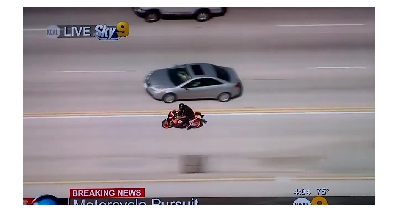

i = 1;
filename = horzcat(Idir(i).folder,'/',Idir(i).name);
I = imresize(imread(filename), scale);

rect = [BB(1, 2)*scale, BB(1, 3)*scale, BB(1, 4)*scale, BB(1, 5)*scale];
IC = imcrop(I, rect);


IQ = insertShape(I, 'Rectangle', rect);
imshow(IQ);


overlapRatio = zeros(1, nf);
overlapRatio(1) = 1

overlapRatio =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0


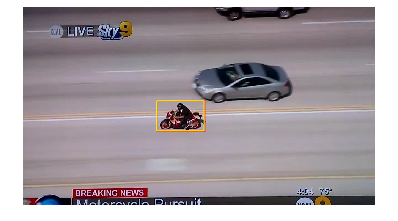


for i = 2:nf
    im_obj = rgb2gray(IC);
    filename = horzcat(Idir(i).folder,'/',Idir(i).name);
    I2 = imresize(imread(filename), scale);
    im_esc = rgb2gray(I2);
    %montage({im_obj, im_esc});
    
    kp_obj = detectSIFTFeatures(im_obj);
    kp_esc = detectSIFTFeatures(im_esc);
    
    [feat_obj, kp_obj] = extractFeatures(im_obj, kp_obj, "Method", "SIFT");
    [feat_esc, kp_esc] = extractFeatures(im_esc, kp_esc, "Method", "SIFT");
    
    pairs = matchFeatures(feat_obj, feat_esc, "MatchThreshold",10);
    
    m_kp_obj = kp_obj(pairs(:,1),:);
    m_kp_esc = kp_esc(pairs(:,2),:);
    
    %figure
    %showMatchedFeatures(im_obj, im_esc,m_kp_obj, m_kp_esc, "montage");
    
    T = estimateGeometricTransform2D(m_kp_obj,m_kp_esc,'affine');
    
    [f, c] = size(im_obj);

    box = [1,1 ; 1,f ; c,f ; c,1 ; 1,1];

    nbox = transformPointsForward(T, box);
    bbox = [nbox(1, :), nbox(3, :) - nbox(1, :)];
    IC = imcrop(I2, bbox);
    
    %IQ = insertShape(I2, 'Rectangle', bbox(1, :));
    %imshow(IQ);

    %calculem el –overlap, intersection over union-- de les finestres 
    overlapRatio(i) = bboxOverlapRatio(bbox(1, :),BB(i,2:5).*scale);


    %mostrem els resultats sobre la imatge
    imshow(I2); % mostra el frame 
    % mostrem els rectangles:  correcte (en groc) i el predit (en vermell)
    rectangle('Position',bbox(1, :),'EdgeColor','red');
    rectangle('Position',BB(i,2:5).*scale,'EdgeColor','yellow');
    drawnow
end

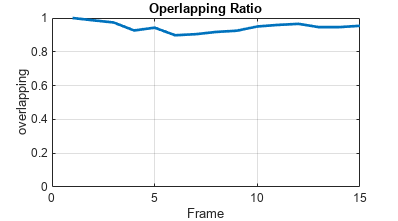


plot(overlapRatio, 'LineWidth', 2); % Gráfica roja con línea punteada de grosor 2
title('Operlapping Ratio'); % Título de la gráfica
xlabel('Frame'); % Etiqueta del eje X
ylabel('overlapping'); % Etiqueta del eje Y
ylim([0, 1]); % Establecer los límites del eje Y de 0 a 1
grid on; % Mostrar una cuadrícula en la gráfica